# **Generación de Números Aleatorios**

`Autor: Dr. Abdelmalik Moujahid`

# **Método de la Transformada Inversa: **

Este método utiliza la función de **distribución acumulativa inversa **para mapear números aleatorios uniformemente 

distribuidos en el intervalo [0,1] a números aleatorios según una distribución específica. 

#### Ejemplo: Distribución Exponencial

Supongamos que queremos generar números aleatorios que sigan una distribución exponencial con parámetro *λ*. 

**La función de densidad de probabilidad (PDF)** para esta distribución es:

$f\left(x;\lambda \;\right)=\lambda \;e^{\left\lbrace -\lambda \;x\right\rbrace }$ para $x\ge 0$

La **función de distribución acumulativa (CDF)** viene dada por:


$$F\left(x;\lambda \;\right)=\int_0^x \lambda \;e^{-\lambda \;t} \textrm{dt}=1-e^{-\lambda \;x}$$


El método de la transformada inversa implica invertir la función de distribución acumulativa y resolver para $x$:


$$F\left(x;\lambda \;\right)=U$$


donde ***U***** es un número aleatorio uniformemente distribuido en el intervalo [0,1]**. 

En el caso de la distribución exponencial, esto se traduce en la siguiente ecuación para *x*:


$$1-e^{-\lambda \;x} =U$$


Resolviendo para $x$,


$$x=-\frac{\ln \left(1-U\right)}{\lambda \;}$$


clear all

syms lambda x t

f = @(t) lambda*exp(-lambda*t);
% distribución acumulativa
F = int(f,t,0,x)

$$F = 1-{\mathrm{e}}^{-\lambda \,x}$$

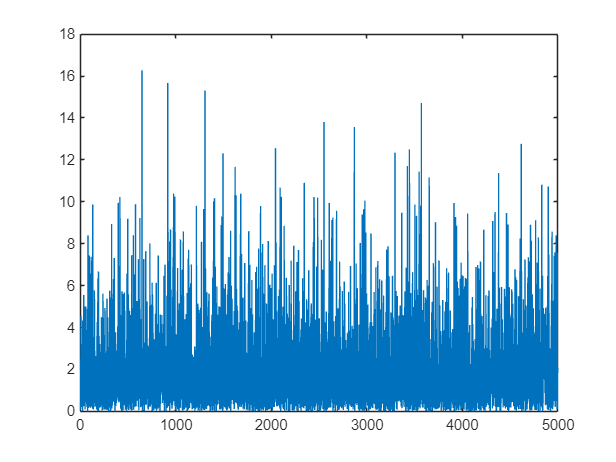

% Parámetro de la distribución exponencial
lambda = 0.5;

% Número de valores a generar
num_values = 5000;

% Generación de números aleatorios con distribución exponencial
random_exponential_numbers = -log(1 - rand(1, num_values)) / lambda;

% Mostrar resultados
plot(random_exponential_numbers);

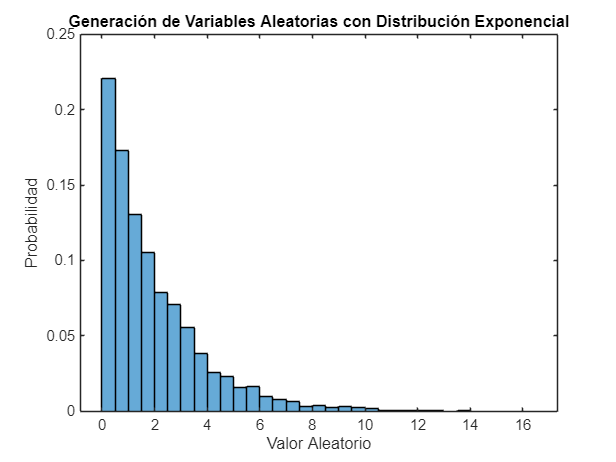

% Visualizar los resultados
histogram(random_exponential_numbers, 'Normalization', 'probability');
title('Generación de Variables Aleatorias con Distribución Exponencial');
xlabel('Valor Aleatorio');
ylabel('Probabilidad');

#### Distribución Uniforme

 **La **función de densidad de probabilidad** (PDF)** para la distribución uniforme es:

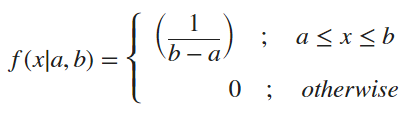

La **función de distribución acumulativa (CDF)** viene dada por:

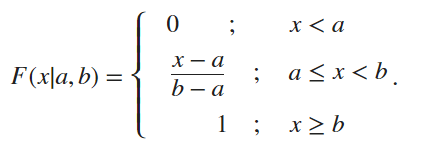

El método de la transformada inversa implica invertir la función de distribución acumulativa y resolver para $x$:

$F\left(x;a,b\;\right)=U=\frac{x-a}{b-a}$ para $a\le x\le b$

Resolviendo para $x$,


$$x=a+\left(b-a\right)\;U$$


Es un generador para una distribución uniforme en el intervalo $\left\lbrack a,b\right\rbrack$.